clear all
close all
clc

**2.1 Probabilidade**

2. Considere o seguinte “jogo”: lanc¸amento com os olhos vendados de n dardos, um de cada vez, para m alvos, garantindo-se que cada dardo atinge sempre um alvo (e apenas 1). 

(a) Estime por simulaçao a probabilidade de nenhum alvo ter sido atingido mais do que uma vez quando n = 20 dardos e m = 100 alvos. 

N = 1e5;
n = 20;
m = 100;
lancamentos = randi(m,n,N);
diferentes = true(1,N);
for coluna = 1:N
    diferentes(coluna) = length(unique(lancamentos(:,coluna))) == n;
end
p1 = sum(diferentes)/N

p1 = 0.1313

(b) Estime por simulac¸ao a probabilidade de pelo menos 1 alvo ter sido atingido 2 ou mais vezes quando n = 20 dardos e m = 100 alvos. 

p2 = 1-p1

p2 = 0.8687

(c) Considere os valores de m = 1000 e m = 100000 alvos. Para cada um destes valores, fac¸a as simulac¸oes necessarias para desenhar um grafico (usando a funcao plot do Matlab) da probabilidade da alinea (b) em func¸ao do n ˜ umero de dardos ´ n. Considere n de 10 a 100 com incrementos de 10. Os 2 graficos devem ser sub-gr ´ aficos de uma mesma figura (use a instruc¸ ´ ao˜ subplot do Matlab). Compare os resultados dos 2 casos e retire conclusoes.

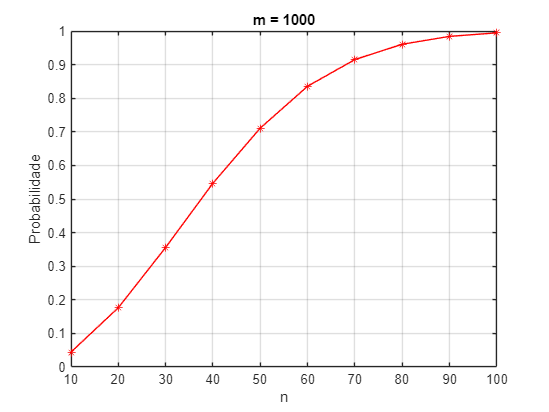

tic
N = 1e5;
ns = 10:10:100;
m = 1000;
res = zeros(1,length(ns));
for i = 1:length(ns)
        n = ns(i);
        lancamentos = randi(m,n,N);
        diferentes = true(1,N);
        for coluna = 1:N
            diferentes(coluna) = length(unique(lancamentos(:,coluna)))<n;
        end
        res(i) = sum(diferentes)/N;
end
figure(1);
plot(ns,res,'r*-'), xlabel('n'), ylabel('Probabilidade'), title('m = 1000'), grid on;

toc

Elapsed time is 6.982716 seconds.


(d) Considere o valor de n = 100 dardos. Fac¸a as simulac¸oes necess ˜ arias para desenhar um gr ´ afico ´ da probabilidade da al´ınea (b) em func¸ao dos valores de m = 200, 500, 1000, 2000, 5000, 10000, 20000, 50000 e 100000 alvos. O que conclui dos resultados obtidos?

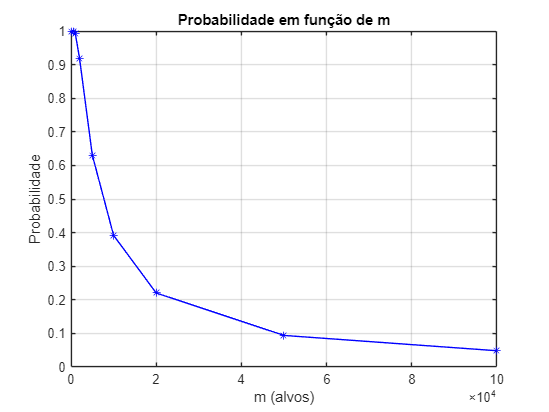

tic
N = 1e5;
n = 100;
ms = [200, 500, 1000, 2000, 5000, 10000, 20000, 50000, 100000];  % Valores de m (alvos)
res = zeros(1,length(ms));
for i = 1:length(ms)
        m = ms(i);
        lancamentos = randi(m,n,N);
        diferentes = true(1,N);
        for coluna = 1:N
            diferentes(coluna) = length(unique(lancamentos(:,coluna)))<n;
        end
        res(i) = sum(diferentes)/N;
end
figure(2);
plot(ms, res, 'b*-'), xlabel('m (alvos)'), ylabel('Probabilidade'), title('Probabilidade em função de m'), grid on;

toc

Elapsed time is 7.854412 seconds.
